# Figure 5A, 5B, 5C, 5D right, S5B, S5C, S6D,S6E

**Load Data**

clear
clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'F036_data.mat'],'S','settings','allIF');
conditions = settings.conditions

conditions = 20×5 cell array
    {'DMSO DMSO'  }    {[1 2 3 4]}    {[ 2]}    {[1]}    {[0 0 0]}
    {'DMSO 2i 10' }    {[1 2 3 4]}    {[ 3]}    {[1]}    {[0 0 0]}
    {'DMSO 2i 5'  }    {[1 2 3 4]}    {[ 4]}    {[1]}    {[0 0 0]}
    {'DMSO 2i 1'  }    {[1 2 3 4]}    {[ 5]}    {[1]}    {[0 0 0]}
    {'DMSO 2i 0.5'}    {[1 2 3 4]}    {[ 6]}    {[1]}    {[0 0 0]}
    {'DMSO RO 10' }    {[1 2 3 4]}    {[ 7]}    {[1]}    {[0 0 0]}
    {'DMSO RO 5'  }    {[1 2 3 4]}    {[ 8]}    {[1]}    {[0 0 0]}
    {'DMSO RO 2'  }    {[1 2 3 4]}    {[ 9]}    {[1]}    {[0 0 0]}
    {'DMSO RO 1'  }    {[1 2 3 4]}    {[10]}    {[1]}    {[0 0 0]}
    {' 2i 1/RO 5' }    {[1 2 3 4]}    {[11]}    {[1]}    {[0 0 0]}
    {'TAK DMSO'   }    {[5 6 7 8]}    {[ 2]}    {[1]}    {[0 0 0]}
    {'TAK 2i 10'  }    {[5 6 7 8]}    {[ 3]}    {[1]}    {[0 0 0]}
    {'TAK 2i 5'   }    {[5 6 7 8]}    {[ 4]}    {[1]}    {[0 0 0]}
    {'TAK 2i 1'   }    {[5 6 7 8]}    {[ 5]}    {[1]}    {[0 0 0]}
    {'TAK 2i 0.5' }    {[5 6 7 8]



framesPerHr = 60/12;
frameDrugAdded = 37;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (frameDrugAdded - S(i).POI)/framesPerHr;
end

drug_time = frameDrugAdded/framesPerHr;

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    apcGate = false(length(dat.POI(:,2)),1);
    apcGateAll = false(length(dat.POI(:,1)),1); 
     crlGate = false(length(dat.POI(:,3)),1);

    for n = 1:length(dat.POI(:,1))
       if dat.POI(n,1) + round(.5*framesPerHr) <= numFrames & dat.POI(n,1) > 1 * framesPerHr
            apcExpressGate(n) = dat.apcNormM(n,dat.POI(n,1) + round(.5*framesPerHr)) < .1 & ...
               dat.apcNormM(n,dat.POI(n,1) - 1 * framesPerHr) > .5 ;
       end
       if dat.POI(n,1) + round(.5*framesPerHr) <= numFrames & dat.POI(n,1) > 1 * framesPerHr
            apcGate(n) = dat.apcNormM(n,dat.POI(n,1) + round(.5*framesPerHr)) < .1 & ...
               dat.apcNormM(n,dat.POI(n,1) - 1 * framesPerHr) > .5 ;
       end

        if dat.POI(n,2) + round(5*framesPerHr) <= numFrames 
            apcGate(n) = dat.apcNuc(n,dat.POI(n,2) + round(5*framesPerHr)) < 400;
            apcGateAll(n) = true;
        end
       if dat.POI(n,1) > 1 * framesPerHr
            crlGate(n) = dat.crlNuc(n,dat.POI(n,1) - 1 * framesPerHr) >  100;
        end

    end
    S(i).apcExpressGate = apcExpressGate;
        S(i).apcGate = apcGate;
S(i).apcGateAll = apcGateAll;

   S(i).crlGate = crlGate;

end

5A left

conds=[1 4 6 20];
timeGate = [6 drug_time];
cols =  [.5 .5 .5 ; .7 .9 .1; 1 .4 .2; .1 .4 1;0 .4 .6; .855 .384 1;0 0 1];
linetype = {'-','-','-','--'};

figure('unit','inches','position',[0 0 4 4])
nexttile
hold on
POI_align = 1;
POI_cal = 3;
data_out = [];
frames_out = [];

for i=1:length(conds)
    data = S(conds(i));
      inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate & (S(conds(i)).POI_realtime(:,3) > drug_time | isnan(S(conds(i)).POI(:,3)) );

    event = data.POI(:,POI_cal);

    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

   y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
     if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
     end 

   plot(x,f, 'Color',cols(i,:),'linestyle',linetype(i),'LineWidth',2);

 
    sum(inds)
end

ans = 908

ans = 975

ans = 1045

ans = 1040

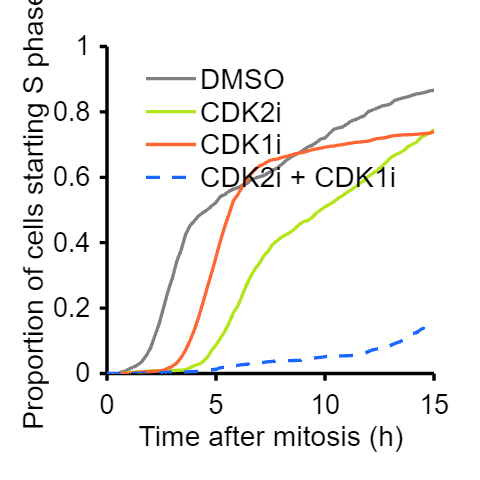



axis square
set(gca,'linewidth',2)
legend('DMSO','CDK2i','CDK1i','CDK2i + CDK1i','Box','off','Location','north','FontSize',17);
xlim([0 15]); 
xticks(0:5:15)
ylim([0 1]);
yticks(0:.2:1)
xlabel('Time after mitosis (h)','FontSize',17)
ylabel('Proportion of cells starting S phase','FontSize',17)
hold on

% print_pdf(['fig_5A_left.pdf'])

5A right

conds=[1 4 6 20];
timeGate = [6 drug_time];
cols =  [.5 .5 .5 ; .7 .9 .1; 1 .4 .2; .1 .4 1;0 .4 .6; .855 .384 1;0 0 1];
linetype = {'-','-','-','--'};

figure('unit','inches','position',[0 0 4 4])
nexttile
hold on
POI_align = 2;
POI_cal = 3;
data_out = [];
frames_out = [];

for i=1:length(conds)
    data = S(conds(i));
      inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate & (S(conds(i)).POI_realtime(:,3) > drug_time | isnan(S(conds(i)).POI(:,3)) );

    event = data.POI(:,POI_cal);

    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

   y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
     if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
     end 
    
   plot(x,f, 'Color',cols(i,:),'linestyle',linetype(i),'LineWidth',2);

 
    sum(inds)
end

ans = 735

ans = 745

ans = 800

ans = 734

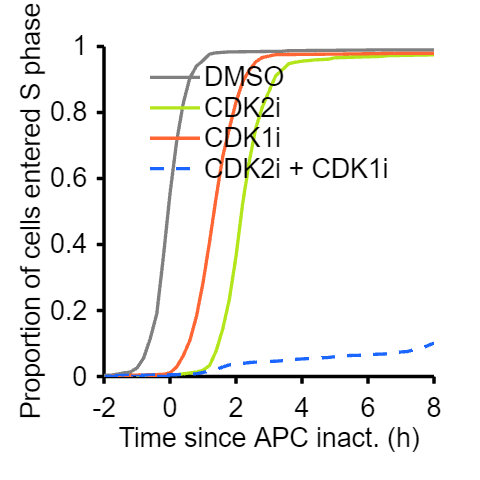



axis square
set(gca,'linewidth',2)
legend('DMSO','CDK2i','CDK1i','CDK2i + CDK1i','Box','off','Location','north','FontSize',16);
xlim([-2 8]); 

ylim([0 1]);
yticks(0:.2:1)
xlabel('Time since APC inact. (h)','FontSize',16)
ylabel('Proportion of cells entered S phase','FontSize',16)
hold on

% print_pdf(['fig_5A_right.pdf'])

conds=[1 11];


colors = [0 0 1;.8 .2 1;.6 .1 .5;.7 .7 .2; 1 .5 .2; 0 .4 .6; .855 .384 1;0 0 1];
linetype = {'-','-','-','--'};
timeGate = [6 drug_time];

figure('unit','inches','position',[0 0 4 3])
hold on
axis square;
POI_align = 3;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
        inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate &S(conds(i)).goodCdk& (S(conds(i)).POI_realtime(:,3) > drug_time | isnan(S(conds(i)).POI(:,3)) );
 sum(inds)


    ydata = data.cdk(inds,:);

    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',1.5,'linestyle',linetype(i)});
end

ans = 728

ans = 757

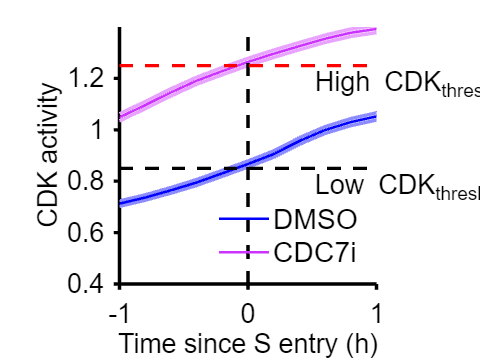


ylabel({'CDK activity'});xlabel('Time since S entry (h)');
legend('DMSO','CDC7i','box','off','Location','southeast','fontsize',17);

xlim([-1 1]); 
ylim([.4 1.4]);
vline([0],'k--')
text(.5,1.17,'High CDK_{thresh}')
hline(1.25,'r--')
hline(.85,'k--')
text(.5,.77,'Low CDK_{thresh}')

5B

conds=[1 4 6 20];
cols =  [.5 .5 .5 ; .7 .9 .1; 1 .4 .2; .1 .4 1;0 .4 .6; .855 .384 1;0 0 1];
linetype = {'-','-','-','--'};
timeGate = [6 drug_time];

figure('unit','inches','position',[0 0 3 3])
hold on

POI_align = 1;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
        inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).goodCdk& S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate & (S(conds(i)).POI_realtime(:,3) > drug_time | isnan(S(conds(i)).POI(:,3)) );
 sum(inds)


    ydata = data.cdk(inds,:);

    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',cols(i,:),'LineWidth',1.5,'linestyle',linetype(i)});
end

ans = 893

ans = 956

ans = 1012

ans = 1016

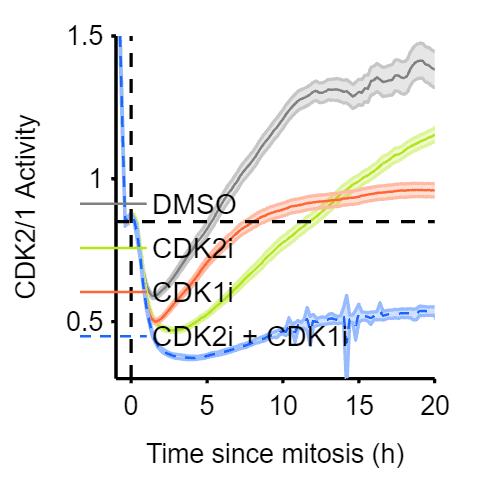


ylabel({'CDK2/1 Activity'});xlabel('Time since mitosis (h)');
legend('DMSO','CDK2i','CDK1i','CDK2i + CDK1i','box','off','Location','southeast','fontsize',17);

xlim([-1 20]); 
xticks(0:5:20)
ylim([.3 1.5]);
yticks(0.5:.5:1.5)
vline([0],'k--')
hline(.85,'k--')
text(25,.77,'Low CDK2/1_{thresh}')

% print_pdf(['fig_5B.pdf'])

5C

conds=[1 4 6];

cols =  [.5 .5 .5 ; .7 .9 .1; 1 .4 .2; .1 .4 1;0 .4 .6; .855 .384 1;0 0 1];
linetype = {'-','-','-','--'};
timeGate = [7 drug_time];

figure('unit','inches','position',[0 0 4 4])
hold on

POI_align = 3;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
        inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).goodCdk& S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate & (S(conds(i)).POI_realtime(:,3) > drug_time | isnan(S(conds(i)).POI(:,3)) );
 sum(inds)


    ydata = data.cdk(inds,:);

    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',cols(i,:),'LineWidth',2,'linestyle',linetype(i)});
end

ans = 302

ans = 300

ans = 310

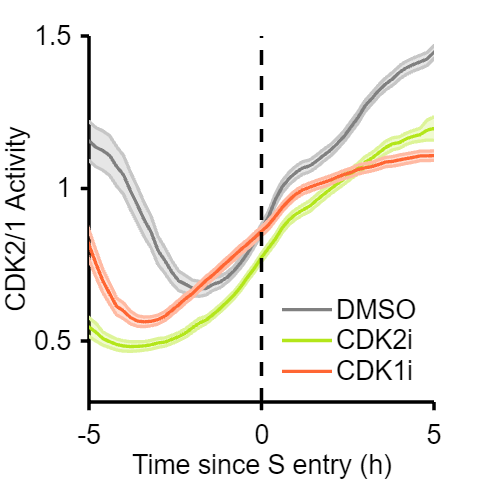


ylabel({'CDK2/1 Activity'});xlabel('Time since S entry (h)');
legend('DMSO','CDK2i','CDK1i','box','off','Location','southeast','fontsize',16);

xlim([-5 5]); 
xticks(-5:5:20)
ylim([.3 1.5]);
yticks(0.5:.5:1.5)
vline([0],'k--')


% print_pdf(['fig_5C.pdf'])

5D right

conds=[11 14 16];
colors =  [1 .4 .2;.7 .9 .1;1 .2 .4;0 .1 1;.6 .1 .5;.7 .7 .2; 1 .5 .2; 0 .4 .6; .855 .384 1;0 0 1];
linetype = {'-','-','--','--'};
timeGate = [6 drug_time];

figure('unit','inches','position',[0 0 4 4])
hold on
axis square;
POI_align = 1;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
         inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate & S(conds(i)).goodCdk& (S(conds(i)).POI_realtime(:,3) > drug_time | isnan(S(conds(i)).POI(:,3)) );
 sum(inds)


    ydata = data.cdk(inds,:);

    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',1.5,'linestyle',linetype(i)});
end

ans = 954

ans = 1093

ans = 1049

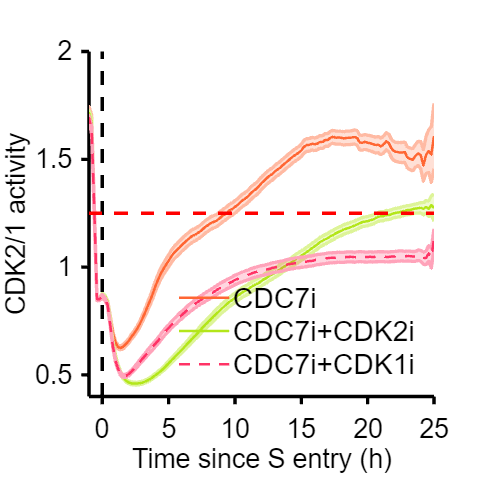


ylabel({'CDK2/1 activity'});xlabel('Time since S entry (h)');
legend('CDC7i','CDC7i+CDK2i','CDC7i+CDK1i','box','off','Location','southeast','fontsize',17);

xlim([-1 25]); 
xticks(0:5:25)
ylim([.4 2]);
yticks(0:.5:2)
vline([0],'k--')
hline(1.25,'r--')

% text(25,1.17,'High CDK_{thresh}')
 % print_pdf(['fig_5D_right.pdf'])



S6B

ans = 893

numcell = 11294

numcell = 11128

numcell = 17004

numcell = 17009

numcell = 11278

ans = 1012

numcell = 727

numcell = 3225

numcell = 3135

numcell = 688

numcell = 3356

ans = 956

numcell = 571

numcell = 4502

numcell = 4677

numcell = 1766

numcell = 4593

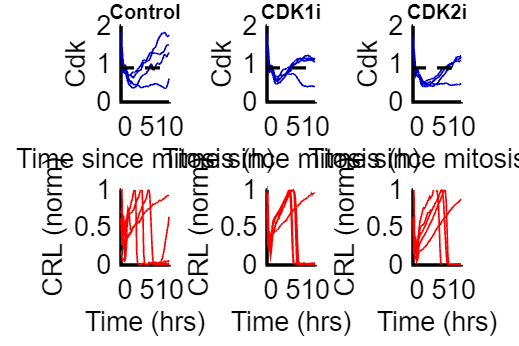

rng(4)
conds=[1 6 4];
timeGate = [6 drug_time];
poiAlign = [ 1];
alignNames = {'Mitosis','APC','CRL on'};
xlimits = {[-1 10],[-5 12],[-5 12]};
for p = 1:length(poiAlign)
  f1= figure('Units', 'Inches', 'Position', [0, 0, 6, 4]);
    names = {'Control','CDK1i','CDK2i'};
    
    for i=1:length(conds)
      
  inds = ~isnan(S(conds(i)).POI(:,1))  &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate & S(conds(i)).goodCdk& (S(conds(i)).POI_realtime(:,3) > drug_time | isnan(S(conds(i)).POI(:,3)) );

    
   cells = find(inds);
sum (inds)
    
        for numcell = randsample(cells,min([5 length(cells)]))'
            numcell
            timeAligned = xTime-S(conds(i)).POI(numcell,poiAlign(p))/framesPerHr;
          
            subplot(2,length(conds),i),hold on
           patchline(timeAligned,nansmooth(S(conds(i)).cdk(numcell,:),3),...
               'edgecolor',[0 0 .8],'linewidth',1,'edgealpha',1);
            title({names{i}},'FontSize',12);
            ylabel('Cdk');
           
            hline (.9,'k--')
            hold on
          
            ylim([0 2]);
            xlim(xlimits{p});
            xlabel('Time since mitosis (h)');
        
            subplot(2,length(conds),i+length(conds)),hold on
            patchline(timeAligned,S(conds(i)).crlNormAct(numcell,:),...
                'edgecolor','r','linewidth',1,'edgealpha',1);
            ylabel('CRL (norm)');
            xlabel('Time (hrs)');
           ylim([0 1]);
            xlim(xlimits{p});
        end
    end
end

% print_pdf(['fig_S6B.pdf'])

S6C

rng(7)
conds=[1 4];
timeGate = [6 drug_time];
poiAlign = [2];
alignNames = {'APC','CRL on'};
xlimits = {[-5 5],[-5 12],[-5 12]};
for p = 1:length(poiAlign)
  f1= figure('Units', 'Inches', 'Position', [0, 0, 6, 6]);
    names = {'Control','CDK2i'};
    
    for i=1:length(conds)
      
  inds = ~isnan(S(conds(i)).POI(:,1))  &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate & S(conds(i)).goodCdk& (S(conds(i)).POI_realtime(:,3) > drug_time | isnan(S(conds(i)).POI(:,3)) );

   % 
   cells = find(inds);
sum (inds)
     % % 
        for numcell = randsample(cells,min([10 length(cells)]))'
            numcell
            timeAligned = xTime-S(conds(i)).POI(numcell,poiAlign(p))/framesPerHr;
            %timeAligned = xFrames-S(conds(i)).filterPOI(numcell,2);
            %dmso = 5557 (5799, 5719, 437,10846,5795), tak = 3757 (3975, 3838, 7073, 3735, 7019) 
          % dmso 1i 10um = 2585, 1692, 2446,2624,725, tak+1i 10um = (
          % 1029,1798, 749, 1897, 852,2948,986) (no s phase cells gating = 3040 812 1061)
          %tak+2i = 260,400
            %2i = 2306,2335
            subplot(2,length(conds),i),hold on
           patchline(timeAligned,nansmooth(S(conds(i)).cdk(numcell,:),3),...
               'edgecolor',[0 0 .8],'linewidth',1,'edgealpha',1);
            title({names{i}},'FontSize',12);
            ylabel('CDK2/1 Activity');
            % hline (1.25,'r--')
            % hline (.9,'k--')
             vline (0,'k--')
            hold on
            % scatter (S(conds(i)).POI_realtime(numcell,3)-S(conds(i)).POI_realtime(numcell,1),S(conds(i)).cdk(numcell,S(conds(i)).POI(numcell,3) ),'magenta')
            % vline (0)
            ylim([0 2]);
            xlim(xlimits{p});
            xlabel('Time since APC/C inact. (h)');
           %  subplot(3,length(conds),i+length(conds)),hold on
           %  patchline(timeAligned,S(conds(i)).apcNormM(numcell,:),...
           %      'edgecolor','r','linewidth',1,'edgealpha',0.2);
           %  title({conditions{conds(i),1}, [' aligned to ' alignNames{(p)}]},'FontSize',12);
           %  ylabel('APC (norm)');
           %  xlabel('Time (hrs)');
           % ylim([0 1]);
           %  xlim(xlimits{p});
           % % 
            subplot(2,length(conds),i+length(conds)),hold on
            patchline(timeAligned,S(conds(i)).apcNormM(numcell,:),...
                'edgecolor','r','linewidth',1,'edgealpha',1);
            ylabel('APC/C reporter');
            xlabel('Time since APC/C inact. (h)');
           ylim([0 1]);
            xlim(xlimits{p});
               vline (0,'k--')
        end
    end
end
figure(f1)
% print_pdf(['fig_S6C'])

S6D

conds=[1 6];
timeGate = [0 drug_time];
cols =  [.5 .5 .5 ; 1 .4 .2; .7 .9 .1; 1 .4 .2; .1 .4 1;0 .4 .6; .855 .384 1;0 0 1];
linetype = {'-','-','-','--'};

figure('unit','inches','position',[0 0 4 4])
nexttile
hold on
POI_align = 1;
POI_cal = 6;
data_out = [];
frames_out = [];

for i=1:length(conds)
    data = S(conds(i));
      inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate & (S(conds(i)).POI_realtime(:,3) > drug_time | isnan(S(conds(i)).POI(:,3)) );

    event = data.POI(:,POI_cal);

    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

   y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
     if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
     end 
    
   plot(x,f, 'Color',cols(i,:),'linestyle',linetype(i),'LineWidth',2);

 
    sum(inds)
end

ans = 1989

ans = 2183

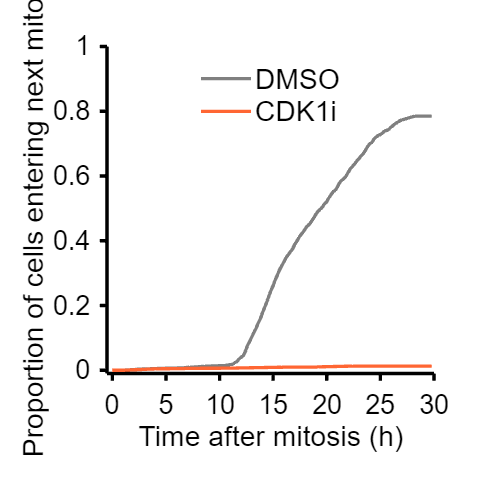



axis square
set(gca,'linewidth',2)
legend('DMSO','CDK1i','Box','off','Location','north','FontSize',17);
xlim([-0.5 30]); 
xticks(0:5:30)
ylim([-0.01 1]);
yticks(0:.2:1)
xlabel('Time after mitosis (h)','FontSize',17)
ylabel('Proportion of cells entering next mitosis','FontSize',17)
hold on

% print_pdf('Fig_S6D.pdf')

S6E

ans = 954

numcell = 4895

numcell = 656

numcell = 607

numcell = 4889

numcell = 13259

ans = 1049

numcell = 1771

numcell = 792

numcell = 2661

numcell = 2831

numcell = 1745

ans = 1093

numcell = 777

numcell = 4742

numcell = 2305

numcell = 3438

numcell = 2147

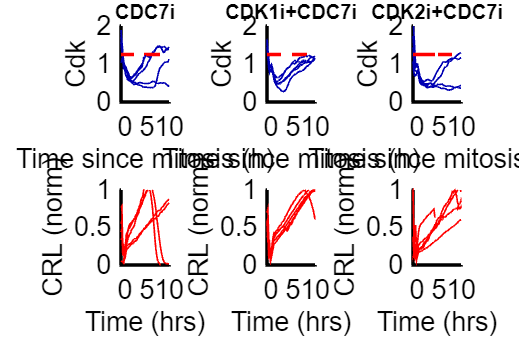

conds=[11 16 14];
poiAlign = [ 1];
alignNames = {'Mitosis','APC','CRL on'};
xlimits = {[-1 10],[-5 12],[-5 12]};
timeGate = [6 drug_time];
for p = 1:length(poiAlign)
  f2= figure('Units', 'Inches', 'Position', [0, 0, 6, 4]);
    names = {'CDC7i','CDK1i+CDC7i','CDK2i+CDC7i'};
    
    for i=1:length(conds)
      
 
    
  inds = ~isnan(S(conds(i)).POI(:,1))  &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate & S(conds(i)).goodCdk& (S(conds(i)).POI_realtime(:,3) > drug_time | isnan(S(conds(i)).POI(:,3)) );

   % 
   cells = find(inds);
sum (inds)
   
        for numcell = randsample(cells,min([5 length(cells)]))'
            numcell
            timeAligned = xTime-S(conds(i)).POI(numcell,poiAlign(p))/framesPerHr;
          
            subplot(2,length(conds),i),hold on
           patchline(timeAligned,nansmooth(S(conds(i)).cdk(numcell,:),3),...
               'edgecolor',[0 0 .7],'linewidth',1,'edgealpha',1);
            title({names{i}},'FontSize',12);
            ylabel('Cdk');
            hline (1.25,'r--')
           
            hold on
          
            ylim([0 2]);
            xlim(xlimits{p});
            xlabel('Time since mitosis (h)');
          
            subplot(2,length(conds),i+length(conds)),hold on
            patchline(timeAligned,S(conds(i)).crlNormAct(numcell,:),...
                'edgecolor','r','linewidth',1,'edgealpha',1);
            ylabel('CRL (norm)');
            xlabel('Time (hrs)');
           ylim([0 1]);
            xlim(xlimits{p});
        end
    end
end

% print_pdf(['fig_S6E.pdf'])

ans = 893

numcell = 17014

numcell = 5628

numcell = 11120

numcell = 11084

numcell = 5461

numcell = 11304

numcell = 533

numcell = 538

numcell = 11085

numcell = 16832

ans = 956

numcell = 532

numcell = 4678

numcell = 4465

numcell = 3042

numcell = 2961

numcell = 3018

numcell = 1557

numcell = 4636

numcell = 3167

numcell = 3095